# `SOLVING THE RNA-FOLDING PROBLEM USING INTEGER LINEAR PROGRAMING`

## `INTEGER LINEAR PROGRAMMING`

`Linear programming is a mathematical modelling technique, where the entire problem statement whatever it may be is boiled to maximization or minimization (basically optimization) of an objective function which must be linear i.e., the degree of the expression must be one, along with a set of linear constraints on the variables which can be equality constraints or inequality constraints. Basically, linear programming in a simple format can be expressed as follows,`


$$\begin{array}{l}
{\textrm{maximize}\;\;\;\;\;\;A}^T x\\
\textrm{subject}\;\textrm{to}\;\;\;\;\;\;\;\textrm{Cx}\le b\;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Dx}=e
\end{array}$$
          
$$\begin{array}{l}
{\textrm{minimize}\;\;\;\;\;\;A}^T x\\
\textrm{subject}\;\textrm{to}\;\;\;\;\;\;\;\textrm{Cx}\ge b\;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Dx}=e
\end{array}$$


`where, 'A' is a column vector of size nx1 (let's say) of constants or weights corresponding to each variable in the objective function, 'x' is variable vector also of size nx1, 'D' and 'E' are constant square matrices of size nxn.`

`Integer linear programing, deals with the same optimization of an objective function over the given constraints, but the the major difference is that, in linear programming the variables need not be integers, but in the case of integer linear programming all the variables must be integers. Hence, in simple words integer linear programming is the optimization of an linear objective function, given a set of constraints on integer variables. So, on looking at the format of integer linear programming, it can be expressed as follows,`


$$\begin{array}{l}
{\textrm{maximize}\;\;\;\;\;\;A}^T x\\
\textrm{subject}\;\textrm{to}\;\;\;\;\;\;\;\textrm{Cx}\le b\;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Dx}=e\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x\ge 0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x\in Z^n 
\end{array}$$
          
$$\begin{array}{l}
{\textrm{minimize}\;\;\;\;\;\;A}^T x\\
\textrm{subject}\;\textrm{to}\;\;\;\;\;\;\;\textrm{Cx}\ge b\;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Dx}=e\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x\ge 0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x\in Z^n 
\end{array}$$


`where, 'A' is a column vector of size nx1 (let's say) of constants or weights corresponding to each variable in the objective function, 'x' is variable vector also of size nx1, 'D' and 'E' are constant square matrices of size nxn.`

## `THE RNA FOLDING PROBLEM`

## `FORMULATION OF RNA-FOLDING INTO ILP PROBLEM`

`As mentioned, RNA has folded structure of existance naturally, where a few of the nucleotides are bonded with each other in an optimized manner, in such a way that the number of binds or interactions present in a particular RNA sequence is maximized as much as possible, along with which a certain rules are to be obeyed while pairing. In order to solve the RNA folding problem using ILP, let us consider a binary variable P corresponding each and every pairs of nucleotide present in the given sequence, in such a way that the value of P(a,b) will be '1' if and only if there is an interaction possible between the `$a^{\textrm{th}}$` nucleotide and `$b^{\textrm{th}}$` nucleotide of the given nucleotide sequence and let us consider a matrix 'P' in order to store all the P(i,j) in an organised manner so as to make all P(i,j) values easily accesible. So 'P' is an upper triangular matrix without a diagonal if we store the neccesary variables alone. Let us understand this with an example. Let us consider an RNA sequence 'seq' which shall be as follows,`


$$\textrm{seq}=\textrm{"UGACU"}\;\;$$


`After assuming the sequence, we need to create the P containing the binary variables P(i,j). since there are 5 nucleotides present in the sequence we need to consider 5x5 matrix.`


$$P=\;\left\lbrack \begin{array}{ccccc}
P_{11}  & P_{12}  & P_{13}  & P_{14}  & P_{15} \\
P_{21}  & P_{22}  & P_{23}  & P_{24}  & P_{25} \\
P_{31}  & P_{32}  & P_{33}  & P_{34}  & P_{35} \\
P_{41}  & P_{42}  & P_{43}  & P_{44}  & P_{45} \\
P_{51}  & P_{52}  & P_{53}  & P_{54}  & P_{55} 
\end{array}\right\rbrack$$


`On observing the variables present in the matrix, we have a set of unnecesary variables populating the matrix. In the case of RNA folding problem, a nucleotide cannot be paired with itself, hence, the variables 'P(i,j)' where 'i' and 'j' are equal actually make no sense. Also, we can observe that there is a redundancy in the variables, for example, the variables P(1,2) and P(2,1) both actually represent the samething, which is the bond or pairing interactions between nucleotide at position 1 and 2, hence, in order to avoid this redundance let us consider only the upper triangular part of our matrix. Hence, the updated 'P' matrix turns out to be,`


$$P=\;\left\lbrack \begin{array}{ccccc}
0 & P_{12}  & P_{13}  & P_{14}  & P_{15} \\
0 & 0 & P_{23}  & P_{24}  & P_{25} \\
0 & 0 & 0 & P_{34}  & P_{35} \\
0 & 0 & 0 & 0 & P_{45} \\
0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$


### `OBJECTIVE FUNCTION`

`Now, the main aim of RNA folding is stability, so, in order to increase the stability of a particular RNA sequence the number of pairings must be maximised as much as possible, which implied that the sum of all variables present in the 'P' matrix is supposed to be maximized, hence the objective function turns out to be,`


$$\sum P\left(i,j\right)\;\forall \;\;i<j\;\textrm{and}\;i,j<\textrm{length}\left(\textrm{RNA}\;\textrm{sequence}\right)$$



$$\begin{array}{l}
\textrm{onjective}\;\textrm{function}\;:\sum P\left(i,j\right)\;+\sum P\left(i^{\prime } ,j^{\prime } \right)\;\;\\
\textrm{where},\textrm{sequence}\left(i,j\right)\in \;\left\lbrack \textrm{AU},\textrm{UA}\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{sequence}\left(i^{\prime } ,j^{\prime } \right)\in \left\lbrack \textrm{CG},\textrm{GC}\right\rbrack 
\end{array}$$


`The objective function of the sample sequence turns out to be as follows,`


$$\begin{array}{l}
\textrm{objective}\;\textrm{function}:\textrm{maximize}-\;P_{12} +P_{13} +P_{14} +P_{15} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;{\;+P}_{23} +P_{24} +P_{25} +P_{34} +P_{35} +P_{45} 
\end{array}$$


### `CONSTRAINTS`

`The constraints which the pairings are supposed to obey are as follows:`

#### `CONSTRAINT-1`

`A nucleotide present in RNA sequence can only interact with it's complement present in the sequence.`` Hence, an 'A' present in the sequnce can be paired only with 'U' and vice-versa, in the same way, a 'C' can only be paired with 'G' and vice-versa. Here, we need to note that the above mentioned are the points where pairing is possible, it need not be that the pairing is compulsary in the above cases, the nucleotides may or may not be paired and that depends upon the forthcoming constraints. So, inorder to fulfill this constraint let us eliminate all the pairs among which pairing is not possible, which means we can make all the P(i,j) zero, where pairing is not possible. `


$$P\left(i,j\right)=0\;\;\forall \;\textrm{seq}\left(i\right),\textrm{seq}\left(j\right)\not\in \left\lbrack \textrm{"AU"},\textrm{"UA"},\textrm{"CG"},\textrm{"GC"}\right\rbrack$$


`Henceforth, we get the following constraints generated for our sequnce 'seq',`


$$\begin{array}{l}
P\left(1,2\right)=0\;\;\;\left\lbrack \textrm{seq}\left(1\right)=U,\;\textrm{seq}\left(2\right)=G\right\rbrack \;\;\;\\
P\left(1,4\right)=0\;\;\;\left\lbrack \textrm{seq}\left(1\right)=U,\;\textrm{seq}\left(4\right)=C\right\rbrack \\
P\left(2,3\right)=0\;\;\;\left\lbrack \textrm{seq}\left(2\right)=G,\;\textrm{seq}\left(3\right)=A\right\rbrack \\
P\left(2,5\right)=0\;\;\;\left\lbrack \textrm{seq}\left(2\right)=G,\;\textrm{seq}\left(5\right)=A\right\rbrack \\
P\left(3,4\right)=0\;\;\;\left\lbrack \textrm{seq}\left(3\right)=A,\;\textrm{seq}\left(4\right)=C\right\rbrack \\
P\left(3,5\right)=0\;\;\;\left\lbrack \textrm{seq}\left(3\right)=A,\;\textrm{seq}\left(5\right)=A\right\rbrack \\
P\left(4,5\right)=0\;\;\;\left\lbrack \textrm{seq}\left(4\right)=C,\;\textrm{seq}\left(5\right)=A\right\rbrack 
\end{array}$$


`In order to make the calculations simple let us update our matrix 'P' and objective function by substituting the value of the above variables as zero. Hence, we get out 'P' matrix to be,`


$$P=\;\left\lbrack \begin{array}{ccccc}
0 & 0 & P_{13}  & 0 & P_{15} \\
0 & 0 & 0 & P_{24}  & 0\\
0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$


`And the objective function to be,`


$$\textrm{objective}\;\textrm{function}:\textrm{maximize}-\;P_{13} +P_{15} +P_{24}$$


#### `CONSTRAINT-2`

`A nucleotide present in RNA sequence can be paired with only one other nucleotide present in the sequence. ``Which means that even if there are multiple complements corresponding to a particular nucleotide, it must be bonded with only one of them. The complement to which the nucleotide is to bonded is governed by the forthcoming set of constraints, the major purpose of this constraint is to limit the number of pairings corresponding to a particular nucleotide to one. In this case also we need to note that, pairing is not mandatory, but if a nucleotide is being paired it must be paired to only one other nucleotide. `


$$\begin{array}{l}
\sum P\left(a\right)+\sum P\left(b\right)\le 1\;\\
\textrm{where},\;a=\left(i,j\right)\forall \;i<j\;\textrm{and}\;b=\left(j,i\right)\forall \;i>j
\end{array}$$


`So, on taking sequence 'seq' as our example, we will be getting the following constraints,`


$$\begin{array}{l}
P\left(1,2\right)+P\left(1,3\right)+P\left(1,4\right)+P\left(1,5\right)\le 1\\
P\left(1,2\right)+P\left(2,3\right)+P\left(2,4\right)+P\left(2,5\right)\le 1\\
P\left(1,3\right)+P\left(2,3\right)+P\left(3,4\right)+P\left(3,5\right)\le 1\\
P\left(1,4\right)+P\left(2,4\right)+P\left(3,4\right)+P\left(4,5\right)\le 1\\
P\left(1,5\right)+P\left(2,5\right)+P\left(3,5\right)+P\left(4,5\right)\le 1
\end{array}$$


`Now, on updating these constraint with the zero values obtained in the first constraint, we get the following,`

 
$$\begin{array}{l}
P\left(1,3\right)\;+\;P\left(1,5\right)\le 1\\
P\left(1,3\right)\le 1\\
P\left(2,4\right)\le 1\\
P\left(1,5\right)\le 1
\end{array}$$


#### `CONSTRAINT-3`

`No two pairings or bonds present in an RNA sequence must cross each other, all the interactions must be in a nested manner.`` The main reason for this is that crossing or non-nested interactions may disturb each other and the net result may reduce the stability of the entire molecule. Adding to this, the compactness of a molecule also increases when it is nested, which in turn increases the stability of an RNA molecule. Let's assume for numbers a, b, c and d in such a way that `$a<b<c<d$` and all these four numbers are less than the length of RNA sequence. So, in order to ensure that no two bonds are crossing, we need to ensure that we don't have simultaneous interactions between seq(a),seq(c) and seq(b),seq(d), so only either of P(a,c) or P(b,d) can be one, for all values of a, b, c and d obeying the above mentioned restrictions.`


$$\begin{array}{l}
P\left(i,j\right)+P\left(i^{\prime } ,j^{\prime } \right)\le 1\;\;\;,\textrm{where}\\
i<i^{\prime } <j<j^{\prime } \;\textrm{and}\;i,i^{\prime } ,j,j^{\prime } <\textrm{length}\left(\textrm{RNA}\;\textrm{sequence}\right)
\end{array}$$


`On applying this constraint to our sequence 'seq' we will get the following,`


$$\begin{array}{l}
P\left(1,3\right)+P\left(3,5\right)\le 1\\
P\left(1,4\right)+P\left(3,5\right)\le 1\\
P\left(1,3\right)+P\left(2,5\right)\le 1\\
P\left(2,4\right)+P\left(3,5\right)\le 1\\
P\left(1,4\right)+P\left(2,5\right)\le 1
\end{array}$$


`Now, on updating these constraint with the zero values obtained in the first constraint, we get the following,`


$$\begin{array}{l}
P\left(1,3\right)+P\left(2,4\right)\le 1\\
P\left(1,3\right)\le 1\\
P\left(2,4\right)\le 1
\end{array}$$



$$\begin{array}{l}
\textrm{constraints}:\;P\left(1,3\right)+P\left(2,4\right)\le 1\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;P\left(1,3\right)\;+\;P\left(1,5\right)\le 1\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;P\left(1,3\right)\le 1\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;P\left(2,4\right)\le 1\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;P\left(1,5\right)\le 1
\end{array}$$


`On solving these constraints and objective function we will get the following as our solution,`


$$\begin{array}{l}
\textrm{solutions}:\;P\left(1,5\right)=1\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;P\left(2,4\right)=1
\end{array}$$


`That is the folded structure of the sequence is in such a way that, the first nucleotide interacts with the fifth one and the second nuclotide interacts with the fourth one simultanously.`

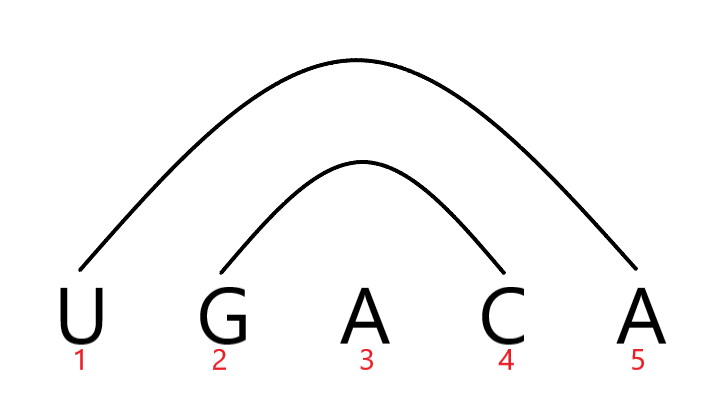

`On pairing the corresponding nucleotides obtained in the solution, we can observe that all the constraints have been followed perfectly. Using this solution we can also generate the dot-bracket notation of the given RNA sequence. In the dot-bracket notation, every nucleotide which is not paired or which is not interacting with any other nucleotide  must be represented as a dot and the nucleotides which are paired are represented by brackets out of which the nucleotide which is closer to the beginning of a sequence is represented with open bracket '(' and the other nucleotide is represented using a closed bracket ')'. `

`The dot-bracket notation corresponding our example sequence 'seq' will be given as,`


$$\textrm{dot}\;\textrm{bracket}="\left(\left(\ldotp \right)\right)"$$


`All the following constraints can also be generated and solved using the matlab sctipt. The script so written simply accepts the RNA sequence as an input and prints it's folded structure. The 'bioinformatics' toolbox of MATLAB is actually used in-order to print the folded structure obtained as a result of optimization which is performed. After performing optimization the solution is then used to generate the dot-bracket notation which is then used by the bioinformatics toolbox to print the structure.`

clc;
clear all;
close all;

seq = 'ACUGU';
n= length(seq);
vars = optimvar("vars",[length(seq),length(seq)],"LowerBound",0,"Type","integer","UpperBound",1);
sum = optimexpr;
st_pairs = ['CG','GC']

st_pairs = 'CGGC'

for i=1:n
    for j=i:n
        seq1 = strcat(seq(i),seq(j));
        if ~any(strcmp(seq1,st_pairs))
            sum = sum + 1.33*vars(i,j);
        else
            sum = sum + vars(i,j);
        end
    end
end
r=[];
c=[];
for i=1:n
    for j=1:n
        if i>=j
            r = [r,i];
            c = [c,j];
        end
    end
end
table(r',c');
rna_fold = optimproblem('ObjectiveSense','maximize');
list1 = [];
for i = 1:length(r)
    eqn = vars(r(i),c(i))==0;
    list1 = [list1;eqn];
end
rna_fold.Constraints.neccesary = list1;
rna_fold.Objective = sum;

possible_pairs = ["AU","UA","CG","GC"];
eqnns1 = [];
for i=1:n
    for j=1:n
        if i<j
            if ~any(strcmp(strcat(seq(i),seq(j)),possible_pairs))
                eqn = vars(i,j) == 0;
                eqnns1 = [eqnns1;eqn];
            end 
        end
    end
end
rna_fold.Constraints.set1 = eqnns1;

eqnns2 = [];
for i=1:n
    eqn = optimexpr;
    for j=1:n
        if i~=j
            if i<j
                eqn = eqn+vars(i,j);
            elseif i>j
                eqn = eqn+vars(j,i);
            end
        end
    end
    eqns = eqn<=1;
    eqnns2 = [eqnns2;eqns];
end
rna_fold.Constraints.set2 = eqnns2;

nums = nchoosek([1:length(seq)],4);
eqnns3 = [];
b = size(nums);
for i=(1:b(1))
    eqn = vars(nums(i,1),nums(i,3))+vars(nums(i,2),nums(i,4))<=1;
    eqnns3 = [eqnns3;eqn];
end
rna_fold.Constraints.set3 = eqnns3;

[sol,fval] = solve(rna_fold);

Solving problem using intlinprog.
LP:                Optimal objective value is -2.660000.                                            


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal value, options.AbsoluteGapTolerance = 0 (the default value). The intcon variables
are integer within tolerance, options.IntegerTolerance = 1e-05 (the default value).



begin = [];
end1 = [];
for i=1:n
    for j=1:n
        if sol.vars(i,j)==1
            begin = [begin,i];
            end1 = [end1,j];
        end
    end
end

dot_bracket = '';
for i=1:length(seq)
    if ismember(i,begin)
        dot_bracket = [dot_bracket,'('];
    elseif ismember(i,end1)
        dot_bracket = [dot_bracket,')'];
    else
        dot_bracket = [dot_bracket,'.'];
    end
end

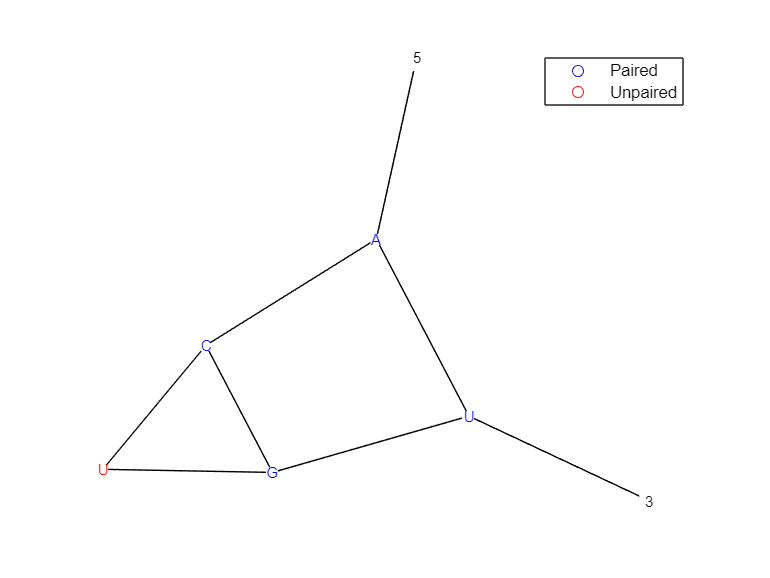

rnaplot(dot_bracket,'Format','Diagram','Sequence',seq)

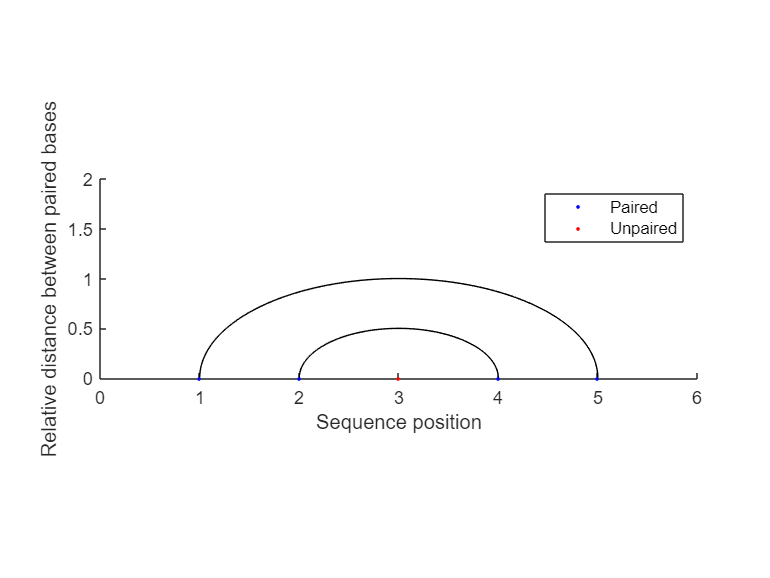

rnaplot(dot_bracket,'Format','Graph')

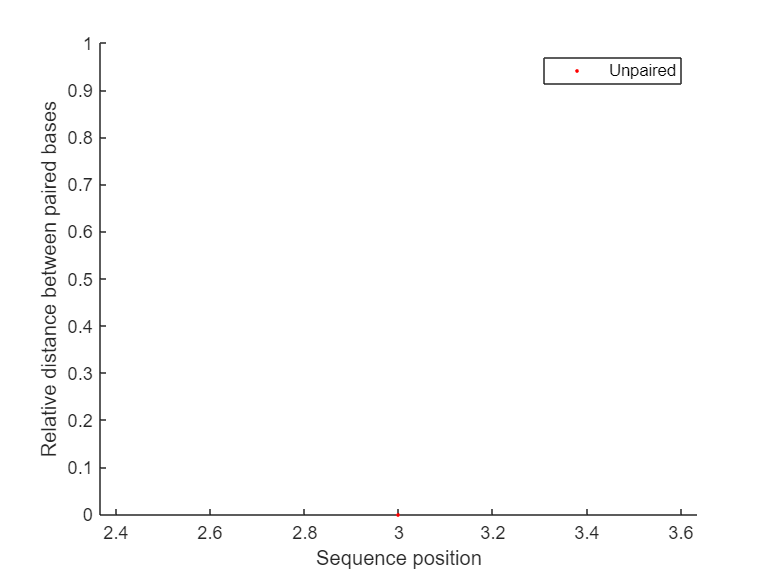

Error using matlab.graphics.axis.Axes/set
Value must be a 1x2 vector of numeric type in which the second element is greater than the first element or is Inf.

Error in rnaplot>localMatrix2graph (line 682)
set(ha, 'Ylim',[0 max(r)]);

Error in rnaplot (line 276)

seq = 'ACUGUACUGUACUGUAC';
ss = rnafold(seq);
dot_bracket2 = '';
for i=1:length(seq)
    if ismember(i,begin)
        dot_bracket2 = [dot_bracket2,'('];
    elseif ismember(i,end1)
        dot_bracket2 = [dot_bracket2,')'];
    else
        dot_bracket2 = [dot_bracket2,'.'];
    end
end

`After computing the results, it can be compared with the results obtain from the built-in method of MATLAB 'bioinformatics' toolbox, which accepts the RNA sequnce as an input and displays it's folded structure.`

Error using matlab.graphics.axis.Axes/set
Value must be a 1x2 vector of numeric type in which the second element is greater than the first element or is Inf.

Error in rnaplot>localMatrix2graph (line 682)
set(ha, 'Ylim',[0 max(r)]);

Error in rnaplot (line 276)

seq = 'ACUGU';
ss = rnafold(seq);
rnaplot(ss,'Format','Graph')